# User Interface Specification Methods

## Setup

Only when recomputing data extracted from apps, the following variables need to be set. Elaborating already extracted data available in the data2.mat file does not require this setup.

Run data-extracting code ONLY after running data-extracting code in selection.mlx, as it is needed to clone the app repositories.

Data-extracting code is commented not to disrupt the data-elaborating workflow.

In order for the data extracting code to work, it is necessary to setup the $PATH environment variable and Ruby environment version to execute terminal commands.

path = '$PATH';
rbenvVersion = "3.0.0";

Moreover, the location of the clones directory must be set:

clonesDir = '.';

## Adoption of User Interface Specification Methods

In order to evaluate the usage of different user interface specification methods, the following code counts the number of occurrences of them for each commit of each app.

load ../../data/data2.mat data

Before looking for UI specification files in repositories the code temporarily removes the `Pods`, `Carthage` and `.build` directories, where resolved dependency files are usually located, thus avoiding to count views not belonging to the app.

- UIKit Storyboards and XIBs: the code looks respectively for `.storyboard` and `.xib` files. Then it counts the occurences of elements, whose names are in the `viewControllersNames` and `viewsNames` arrays, in each of these files. The resulting occurrencies arrays, two for each file, are stored respectively in the `Storyboards` and `xibs` struct arrays of the corresponding commit.

- UIKit Views, ViewControllers specified in Swift and SwiftUI Views: to count the occurrencies of these elements, I modified the Sitrep syntax analyser tool. This tool must be installed before executing the code running the `make install` terminal command inside its main directory. The code invokes Sitrep on the main directory project, that is, where the main `.xcodeproj` package is located (whose name is, again, in column 11). Sitrep returns a JSON that the code elaborates to store the occurrencies respectively in the `UIKitViewsSwift`, `UIKitViewControllersSwift`, `SwiftUIViews `structs of each commit. Each of these structs contains an overall `count` value and a `classes `struct having as fields the name of the classes and as values the occurrencies of that class.

- UIKit Views, ViewControllers specified in Objective-C: to count the occurrencies of these elements, the following code searches in each `.h` file for classes that inherit from classes whose name begins with "UI" and ends with "View" for views, and classes whose name begins with "UI" and ends with "Controller" for viewControllers. The final results are stored, in a similar way to UIKit Views and ViewControllers specified in Swift, respecitvely in the `UIKitViewsObjC `and `UIKitViewControllersObjC` structs of each commit.

% cd(clonesDir)
% 
% viewControllersNames = ["viewController" "tableViewController" "navigationController" "collectionViewController" "hostingController" "tabBarController" "splitViewController" "pageViewController" "glkViewController" "avPlayerViewController" "lookAroundViewController"];
% viewsNames = ["view", "containerView", "textView", "scrollView", "stackView", "imageView", "collectionView", "collectionReusableView", "mapView", "mtkView", "glkView", "sceneKitView", "skView", "arscnView", "arskView", "roomCaptureView", "arView", "wkWebView", "webView", "progressView", "activityIndicatorView", "pickerView"];
% 
% 
% for k=1:size(data)
%     cd(clonesDir)
%     for vc=1:size(data{k, 10})
%         toSave = true; % change this variable to true to repeat the analysis for this tag
%         if not(isfield(data{k, 10}(vc), "SwiftUIViews")) || isempty(data{k, 10}(vc).SwiftUIViews) || toSave
%             pathToExplore = fullfile(clonesDir, data{k,8});
%             cd(pathToExplore)
%             system("git checkout --force " +  data{k, 10}(vc).tag, "PATH", path, "RBENV_VERSION", rbenvVersion);
%             
%             for j=1:length(data{k, 11})
%                 if isfolder(data{k, 11}(j)) && isfile(fullfile(data{k, 11}(j), "/project.pbxproj"))
%                     pathToExplore = fullfile(pathToExplore, data{k, 11}(j), "..");
%                     break
%                 end
%             end
%     
%             cd(pathToExplore)
% 
%             system("find . -name Pods -exec rm -rf {} \;", "PATH", path, "RBENV_VERSION", rbenvVersion);
%             system("find . -name Carthage -exec rm -rf {} \;", "PATH", path, "RBENV_VERSION", rbenvVersion);
%             system("find . -name .build -exec rm -rf {} \;", "PATH", path, "RBENV_VERSION", rbenvVersion);
%                     
%             system("sitrep -f json > " + clonesDir + "/stats.json", "PATH", path, "RBENV_VERSION", rbenvVersion);
%             cd(clonesDir)
%             jsonFile = fileread("stats.json");
%             stats = jsondecode(jsonFile);
%     
%             for q=1:size(stats.inheritances)
%                 stats.inheritances(q).name = convertCharsToStrings(stats.inheritances(q).name);
%             end
%     
%             cd(pathToExplore)
%             hFiles = dir("**/*.h");
%     
%             classes = {};
%             for q=1:size(hFiles)
%                 try
%                     file = fileread(fullfile(hFiles(q).folder, hFiles(q).name));
%                 catch
%                     continue
%                 end
%                 name = "";
%                 inherits = "";
%                 if contains(file, "@interface")
%                     declaration = extractBetween(file, "@interface", "@end");
%     
%                     for t=1:size(declaration)
%                         name(t) = "";
%                         inherits(t) = "";
%                         if contains(declaration(t), "{")
%                             declaration(t) = extractBefore(declaration(t), "{"); 
%                         else
%                             if contains(declaration(t), "-")
%                                 declaration(t) = extractBefore(declaration(t), "-");
%                             end
%     
%                             if contains(declaration(t), "+")
%                                 declaration(t) = extractBefore(declaration(t), "+");
%                             end
%     
%                             if contains(declaration(t), "@property")
%                                 declaration(t) = extractBefore(declaration(t), "@property");
%                             end
%                         end
%     
%                         if contains(declaration(t), ":")
%                             name(t) = strtrim(extractBefore(declaration(t), ":"));
%                             inherits(t) = strtrim(extractAfter(declaration(t), ":"));
%                         else
%                             name(t) = strtrim(declaration(t));
%                         end
%     
%                         if contains(inherits(t), "<")
%                             inherits(t) = extractBefore(inherits(t), "<");
%                         end
%     
%                         if contains(inherits(t), "@property")
%                             inherits(t) = extractBefore(inherits(t), "@property");
%                         end
% 
%                         if contains(inherits(t), "#else")
%                             inherits(t) = extractBefore(inherits(t), "#else");
%                         end
% 
%                         classes{end + 1, 1} = strtrim(name(t));
%                         classes{end, 2} = strtrim(inherits(t));
%                     end
%                 end
%             end
%     
%             cd(pathToExplore)
%             mFiles = dir("**/*.m");
%            
%             data{k, 10}(vc).SwiftUIViews = struct;
%             data{k, 10}(vc).SwiftUIViews.count = sum(cell2mat(struct2cell(stats.inheritances([stats.inheritances.name] == "SwiftUI.View").classes)));
%             data{k, 10}(vc).SwiftUIViews.classes = stats.inheritances([stats.inheritances.name] == "SwiftUI.View").classes;
%             data{k, 10}(vc).UIKitViewsSwift = struct;
%             data{k, 10}(vc).UIKitViewsSwift.count = sum(cell2mat(struct2cell(stats.inheritances([stats.inheritances.name] == "UIView").classes)));
%             data{k, 10}(vc).UIKitViewsSwift.classes = stats.inheritances([stats.inheritances.name] == "UIView").classes;
%             data{k, 10}(vc).UIKitViewControllersSwift = struct;
%             data{k, 10}(vc).UIKitViewControllersSwift.count = sum(cell2mat(struct2cell(stats.inheritances([stats.inheritances.name] == "UIViewController").classes)));
%             data{k, 10}(vc).UIKitViewControllersSwift.classes = stats.inheritances([stats.inheritances.name] == "UIViewController").classes;
%             
%             if size(classes) > 0
%                 UIKitViewsObjC = struct;
%                 UIKitViewControllersObjC = struct;
%                 for c=1:size(classes)
%                     if startsWith(classes{c, 2}, 'UI') && endsWith(classes{c, 2}, 'View')
%                         if isfield(UIKitViewsObjC, classes{c, 2})
%                             UIKitViewsObjC.(classes{c,2}) = UIKitViewsObjC.(classes{c,2}) + 1;
%                         else 
%                             UIKitViewsObjC.(classes{c,2}) = 1;
%                         end
%                     elseif startsWith(classes{c, 2}, 'UI') && endsWith(classes{c, 2}, 'Controller')
%                         if isfield(UIKitViewControllersObjC, classes{c, 2})
%                             UIKitViewControllersObjC.(classes{c,2}) = UIKitViewControllersObjC.(classes{c,2}) + 1;
%                         else 
%                             UIKitViewControllersObjC.(classes{c,2}) = 1;
%                         end
%                     end
%                 end
%                 data{k, 10}(vc).UIKitViewsObjC = struct;
%                 data{k, 10}(vc).UIKitViewControllersObjC = struct;
%                 data{k, 10}(vc).UIKitViewsObjC.count = sum(cell2mat(struct2cell(UIKitViewsObjC)));
%                 data{k, 10}(vc).UIKitViewsObjC.classes = UIKitViewsObjC;
%                 data{k, 10}(vc).UIKitViewControllersObjC.count = sum(cell2mat(struct2cell(UIKitViewControllersObjC)));
%                 data{k, 10}(vc).UIKitViewControllersObjC.classes = UIKitViewControllersObjC;
%             else
%                 data{k, 10}(vc).UIKitViewsObjC = struct;
%                 data{k, 10}(vc).UIKitViewControllersObjC = struct;
%                 data{k, 10}(vc).UIKitViewsObjC.count = 0;
%                 data{k, 10}(vc).UIKitViewControllersObjC.count = 0;
%             end
%             
%             "analyzed commit "+ vc + " out of " + length(data{k, 10}) + " of app " + k
%     
%             cd(pathToExplore)
%             storyboards = dir("**/*.storyboard");
%     
%             data{k, 10}(vc).Storyboards = struct;
%             for q=1:size(storyboards)
%                 file = fileread(fullfile(storyboards(q).folder, storyboards(q).name));
% 
%                 viewControllersCounts = zeros(length(viewControllersNames), 1);
%                 
%                 for vcs = 1:length(viewControllersNames)
%                     positions = strfind(file, "<" + viewControllersNames(vcs));
%                     viewControllersCounts(vcs) = viewControllersCounts(vcs) + length(positions);
%                 end
%                 
%                 viewsCounts = zeros(length(viewsNames), 1);
%                 
%                 for v = 1:length(viewsNames)
%                     positions = strfind(file, "<" + viewsNames(v));
%                     viewsCounts(v) = viewsCounts(v) + length(positions);
%                 end
%                 
%                 data{k, 10}(vc).Storyboards(q).viewControllers = viewControllersCounts;
%                 data{k, 10}(vc).Storyboards(q).views = viewsCounts;
%             end
%     
%             xibs = dir("**/*.xib");
%             data{k, 10}(vc).xibs = struct;
% 
%             for q=1:size(xibs)
%                 file = fileread(fullfile(xibs(q).folder, xibs(q).name));
% 
%                 viewControllersCounts = zeros(length(viewControllersNames), 1);
%                 
%                 for vcs = 1:length(viewControllersNames)
%                     positions = strfind(file, "<" + viewControllersNames(vcs));
%                     viewControllersCounts(vcs) = viewControllersCounts(vcs) + length(positions);
%                 end
%                 
%                 viewsCounts = zeros(length(viewsNames), 1);
%                 
%                 for v = 1:length(viewsNames)
%                     positions = strfind(file, "<" + viewsNames(v));
%                     viewsCounts(v) = viewsCounts(v) + length(positions);
%                 end
%                 
%                 data{k, 10}(vc).xibs(q).viewControllers = viewControllersCounts;
%                 data{k, 10}(vc).xibs(q).views = viewsCounts;
%             end
% 
%             toSave = true || toSave;
%             "analyzed commit "+ vc + " out of " + length(data{k, 10}) + " of app " + k
%         else
%             toSave = false || toSave;
%             "ignored commit "+ vc + " out of " + length(data{k, 10}) + " of app " + k
%         end
%     end
% end

The following code generates, from the obtained data, four arrays containing the numbers of apps adopting SwiftUI views, UIKit ViewControllers (both in Swift and Objective-C), UIKit Views (both in Swift and Objective-C) and Storyboards.

SwiftUI = [];
UIKitVC = [];
UIKitV = [];
Storyboards = [];

for vc = 1:size(data)
    hasSwiftUI = false;
    if (data{vc,10}(end).SwiftUIViews.count > 0)
        hasSwiftUI = true;
        SwiftUI(end+1, 1) = vc;
    end
    
    hasUIKitViewControllers = false;
    if data{vc,10}(end).UIKitViewControllersObjC.count + data{vc,10}(end).UIKitViewControllersSwift.count > 0
        hasUIKitViewControllers = true;
        UIKitVC(end+1, 1) = vc;
    end

    hasUIKitViews = false;
    if data{vc,10}(end).UIKitViewsObjC.count + data{vc,10}(end).UIKitViewsSwift.count > 0
        hasUIKitViews = true;
        UIKitV(end+1, 1) = vc;
    end

    hasStoryboards = false;
    if (isfield(data{vc,10}(end),"Storyboards") && length(data{vc,10}(end).Storyboards) > 1) || isfield(data{vc,10}(end).xibs, "views") || isfield(data{vc,10}(end).xibs, "viewControllers")
        hasStoryboards = true;
        Storyboards(end+1, 1) = vc;
    end
end

SwiftUI'

ans =      2     6     7     9    10    15    18    21    22    23    24    26    28    29    32    34    35    38    39    40    46    47    48    50    52    53    54    55    57    60    66    69    70    72    73    74    76    77    79    81    83    86    88    92    95    99   105   108   109   112


UIKitVC'

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    27    28    30    31    33    34    35    36    37    38    39    40    41    42    43    44    45    47    49    50    51    52    53    54    56


UIKitV'

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    27    28    30    31    33    34    35    36    37    38    39    40    41    42    43    44    45    47    49    50    51    52    53    54    56    57


Storyboards'

ans =      1     2     3     4     5     6     7     8     9    10    11    12    14    15    16    17    18    19    20    21    22    23    25    27    29    31    33    34    35    36    37    38    40    41    44    47    49    50    51    52    54    56    57    58    59    60    61    62    63    64


## UIKit vs SwiftUI

Data obtained before is enough to evaluate how the transition from UIKit to SwiftUI took place.

The following code shows a plot highliting the presence of SwiftUI Views in each commit. Orange commits have at least one SwiftUI view.

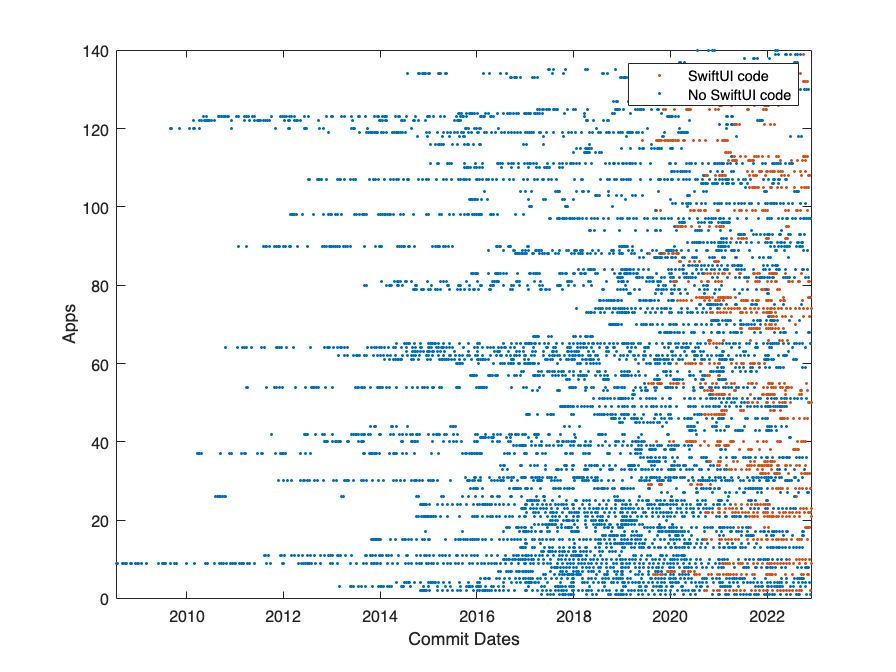

for vc = 1:length(data)
    s = 1;
    o = 1;
    noSwiftUIDates = NaT;
    swiftUIDates = NaT;

    for j=1:length(data{vc,10})
        if data{vc,10}(j).SwiftUIViews.count > 0
            swiftUIDates(s) = data{vc, 10}(j).dateTime;
            s = s + 1;
        else
            noSwiftUIDates(o) = data{vc, 10}(j).dateTime;
            o = o + 1;
        end
    end

    plot(swiftUIDates, repmat(vc, length(swiftUIDates)), '.', 'Color', "#D95319");
    hold on;
    plot(noSwiftUIDates, repmat(vc, length(noSwiftUIDates)), '.', 'Color', "#0072BD");
    hold on;
end
legend("SwiftUI code", "No SwiftUI code")
xlabel("Commit Dates")
ylabel("Apps")

To analyse how the transition from UIKit to SwiftUI took place, I manually divided the apps which introduced SwiftUI into four categories, by inspecting the plots generated by the following code, which shows the behaviour of app 23.

appToShow = 22

appToShow = 22

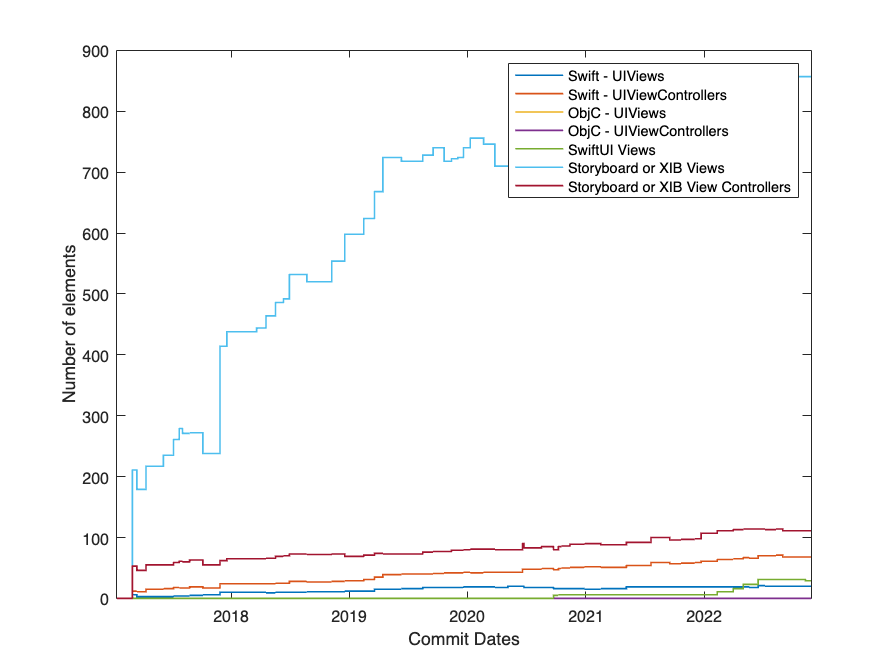

appsWithSwiftUI = [];
appsStartingWithSwiftUI = [];
for i=1:length(data)
    if data{i, 10}(end).SwiftUIViews.count > 0
    appsWithSwiftUI(end+1) = i;
    end
    if data{i, 10}(1).SwiftUIViews.count > 0
    appsStartingWithSwiftUI(end+1) = i;
    end
end

sizes = zeros(length(appsWithSwiftUI), 1);
s = 1;
for i=appToShow
    UIViewsSwift = [];
    UIViewControllersSwift = [];
    UIViewsObjC = [];
    UIViewControllersObjC = [];
    swiftUIViews = [];
    storyboardViews = [];
    storyboardViewControllers = [];
    xibViews = [];
    xibViewControllers = [];
    dates = datetime;
    
    for j=1:length(data{i, 10})
        UIViewsSwift(end + 1) = data{i, 10}(j).UIKitViewsSwift.count;
        UIViewControllersSwift(end + 1) = data{i, 10}(j).UIKitViewControllersSwift.count;
        UIViewsObjC(end + 1) = data{i, 10}(j).UIKitViewsObjC.count;
        UIViewControllersObjC(end + 1) = data{i, 10}(j).UIKitViewControllersObjC.count;
        swiftUIViews(end + 1) = data{i, 10}(j).SwiftUIViews.count;
        views = zeros(22, 1);
        viewControllers = zeros(11, 1);
        xibInViews = zeros(22, 1);
        xibInViewControllers = zeros(11, 1);
        for t=1:length(data{i, 10}(j).Storyboards)
            if isfield(data{i, 10}(j).Storyboards(t), "views")
                views = views + data{i, 10}(j).Storyboards(t).views;
            end
            if isfield(data{i, 10}(j).Storyboards(t), "viewControllers")
            viewControllers = viewControllers + data{i, 10}(j).Storyboards(t).viewControllers;
            end
        end
        for t=1:length(data{i, 10}(j).xibs)
            if isfield(data{i, 10}(j).xibs(t), "views")
                xibInViews = views + data{i, 10}(j).xibs(t).views;
            end
            if isfield(data{i, 10}(j).xibs(t), "viewControllers")
            xibInViewControllers = xibInViewControllers + data{i, 10}(j).xibs(t).viewControllers;
            end
        end
        storyboardViews(end + 1) = sum(views) + sum(xibInViews);
        storyboardViewControllers(end + 1) = sum(viewControllers) + sum(xibInViewControllers);
        dates(end + 1) = data{i, 10}(j).dateTime;
    end
    dates(1) = [];

    dim = UIViewsSwift(end) + UIViewControllersSwift(end) + UIViewsObjC(end)+ UIViewControllersObjC(end) + swiftUIViews(end) + storyboardViews(end) + storyboardViewControllers(end);
    sizes(s) = dim;
    s = s + 1;

    figure('Name',  i + " " + data{i, 8});
    Y = [UIViewsSwift', UIViewControllersSwift', UIViewsObjC', UIViewControllersObjC', swiftUIViews', storyboardViews', storyboardViewControllers'];
    stairs(dates, Y, 'LineWidth', 1);
    legend("Swift - UIViews", "Swift - UIViewControllers", "ObjC - UIViews", "ObjC - UIViewControllers", "SwiftUI Views", "Storyboard or XIB Views", "Storyboard or XIB View Controllers")
    xlabel("Commit Dates")
    ylabel("Number of elements")
end

The four categories are: 

- SwiftUI from the beginning: `appsSwiftUIOnly`

- Rewritten in SwiftUI: `rewrittenInSwiftUI`

- Introduced a small quantity of SwiftUI: `smallSwiftUI. widgets `contains the numbers of  `smallSwiftUI `apps which introduced Home Screen Widgets, available only in SwiftUI.

- Introduced a big quantity of SwiftUI: `bigSwiftUI`

appsSwiftUIOnly = [29 32 48 55 66 69 72 86 92 95 99 105 108 112 113 117 126 129 131 132 136]

appsSwiftUIOnly =     29    32    48    55    66    69    72    86    92    95    99   105   108   112   113   117   126   129   131   132   136


rewrittenInSwiftUI = [26 46 52 79 88 109 114 121]

rewrittenInSwiftUI =     26    46    52    79    88   109   114   121


smallSwiftUI = [2 6 9 10 15 18 21 22 23 28 34 35 38 39 40 47 50 54 57 60 70 73 76 81 83 125 133 134 135 139]

smallSwiftUI =      2     6     9    10    15    18    21    22    23    28    34    35    38    39    40    47    50    54    57    60    70    73    76    81    83   125   133   134   135   139


bigSwiftUI = [7 24 53 74 77]

bigSwiftUI =      7    24    53    74    77


widgets = [2 6 15 18 22 23 28 34 35 47 57 73 133]

widgets =      2     6    15    18    22    23    28    34    35    47    57    73   133


The following code shows how many apps belong to each category

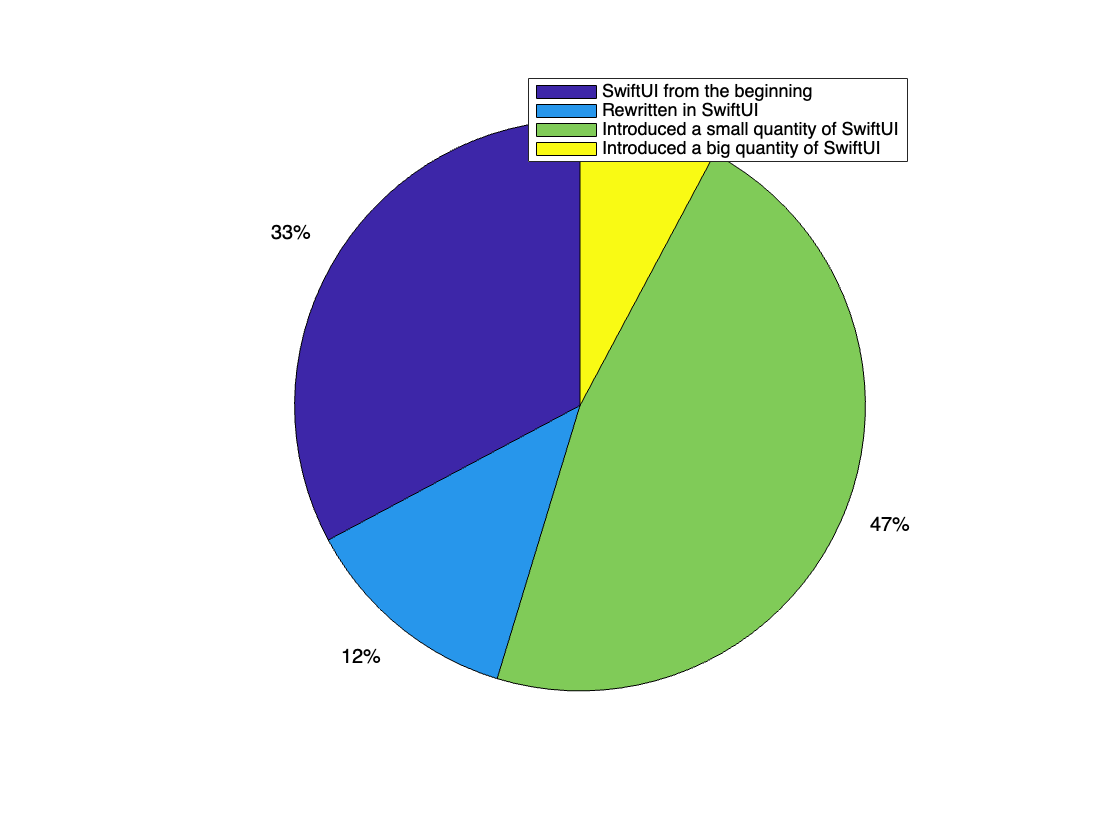

figure;
pie([length(appsSwiftUIOnly), length(rewrittenInSwiftUI), length(smallSwiftUI), length(bigSwiftUI)])
legend("SwiftUI from the beginning", "Rewritten in SwiftUI", "Introduced a small quantity of SwiftUI", "Introduced a big quantity of SwiftUI")

The following code evaluates qualitatively the complexity of views in apps belonging to the categories. To do so, it computes a complexity value for each commit consisting of the sum of occurrences of view specification methods:

dim = zeros(length(data), 1);

sizes = zeros(length(data), 1);
for i=1:size(data)
    UIViewsSwift = [];
    UIViewControllersSwift = [];
    UIViewsObjC = [];
    UIViewControllersObjC = [];
    swiftUIViews = [];
    storyboardViews = [];
    storyboardViewControllers = [];
    xibViews = [];
    xibViewControllers = [];
    
    for j=length(data{i, 10})
        UIViewsSwift(end + 1) = data{i, 10}(j).UIKitViewsSwift.count;
        UIViewControllersSwift(end + 1) = data{i, 10}(j).UIKitViewControllersSwift.count;
        UIViewsObjC(end + 1) = data{i, 10}(j).UIKitViewsObjC.count;
        UIViewControllersObjC(end + 1) = data{i, 10}(j).UIKitViewControllersObjC.count;
        swiftUIViews(end + 1) = data{i, 10}(j).SwiftUIViews.count;
        views = zeros(22, 1);
        viewControllers = zeros(11, 1);
        xibInViews = zeros(22, 1);
        xibInViewControllers = zeros(11, 1);
        for t=1:length(data{i, 10}(j).Storyboards)
            if isfield(data{i, 10}(j).Storyboards(t), "views")
                views = views + data{i, 10}(j).Storyboards(t).views;
            end
            if isfield(data{i, 10}(j).Storyboards(t), "viewControllers")
            viewControllers = viewControllers + data{i, 10}(j).Storyboards(t).viewControllers;
            end
        end
        for t=1:length(data{i, 10}(j).xibs)
            if isfield(data{i, 10}(j).xibs(t), "views")
                xibInViews = views + data{i, 10}(j).xibs(t).views;
            end
            if isfield(data{i, 10}(j).xibs(t), "viewControllers")
            xibInViewControllers = xibInViewControllers + data{i, 10}(j).xibs(t).viewControllers;
            end
        end
        xibViews(end + 1) = sum(xibInViews);
        xibViewControllers(end + 1) = sum(xibInViewControllers);
        storyboardViews(end + 1) = sum(views);
        storyboardViewControllers(end + 1) = sum(viewControllers);
    end

    dim(i) = UIViewsSwift(end) + UIViewsObjC(end) + UIViewControllersSwift(end) + UIViewControllersObjC(end) + swiftUIViews(end) + storyboardViews(end) + storyboardViewControllers(end) + xibViews(end) + xibViewControllers(end);
end


This is the average dimension of apps which adopted SwiftUI

mean(dim(appsWithSwiftUI))

ans = 201.0469

This is the average dimension of SwiftUI apps from the beginning

mean(dim(appsSwiftUIOnly))

ans = 31.6190

This is the average dimension of UIKit apps that introduced at some point SwiftUI

mean(dim(union(union(rewrittenInSwiftUI, smallSwiftUI), bigSwiftUI)))

ans = 283.7907

This is the average dimension of UIKit apps that were completely rewritten in SwiftUI

mean(dim(rewrittenInSwiftUI))

ans = 39.6250

The following code draws two histograms showing the adoption of SwiftUI in apps having the first commit after June 3, 2019, when SwiftUI was introduced.

The `appsSwiftUIOnly` array contains the numbers of apps adopting only SwiftUI instead of UIKit since the beginning, the `appsWithSwiftUI `array contains the numbers of apps adopting both UIKit and SwiftUI.

`appsAfter2019` contains the numbers of all app introduced after June 3, 2019.

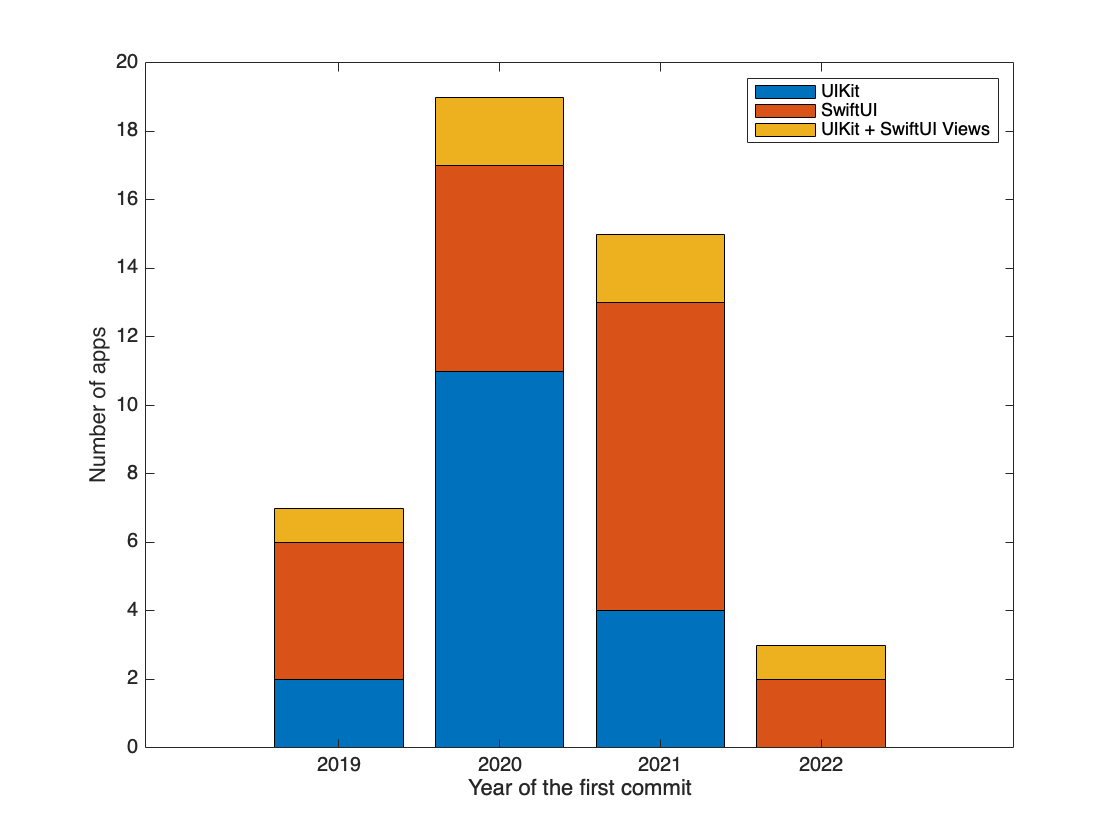

count = 0;
appsAfter2019 = [];
appsWithSwiftUI = union(rewrittenInSwiftUI, union(smallSwiftUI, bigSwiftUI));

for i=1:length(data)
    if data{i, 10}(1).dateTime > datetime("2019-06-03",'InputFormat','yyyy-MM-dd')
        appsAfter2019(end + 1) = i;
    end
end

appsAfter2019Both = intersect(setdiff(appsAfter2019, appsSwiftUIOnly), appsWithSwiftUI);
appsAfter2019UIKit = setdiff(setdiff(appsAfter2019, appsSwiftUIOnly), appsAfter2019Both);
appsSwiftUIOnly = intersect(appsAfter2019, appsSwiftUIOnly);

UIKit= datetime;
UIKitCounts = [0, 0, 0, 0];
j = 1;
for i=appsAfter2019UIKit
    k = year(data{i, 10}(1).dateTime) - 2019 + 1;
    UIKitCounts(k) = UIKitCounts(k) + 1;
    j = j + 1;
end

both = datetime;
bothCounts = [0, 0, 0, 0];
j = 1;
for i=appsAfter2019Both
    k = year(data{i, 10}(1).dateTime) - 2019 + 1;
    bothCounts(k) = bothCounts(k) + 1;
    j = j + 1;
end

swiftUI = datetime;
swiftUICounts = [0, 0, 0, 0];
j = 1;
for i=appsSwiftUIOnly
    k = year(data{i, 10}(1).dateTime) - 2019 + 1;
    swiftUICounts(k) = swiftUICounts(k) + 1;
    j = j + 1;
end

figure;
bar([2019, 2020, 2021, 2022], [UIKitCounts; swiftUICounts; bothCounts], 'stacked');

legend("UIKit", "SwiftUI", "UIKit + SwiftUI Views")
xlabel('Year of the first commit') 
ylabel('Number of apps') 

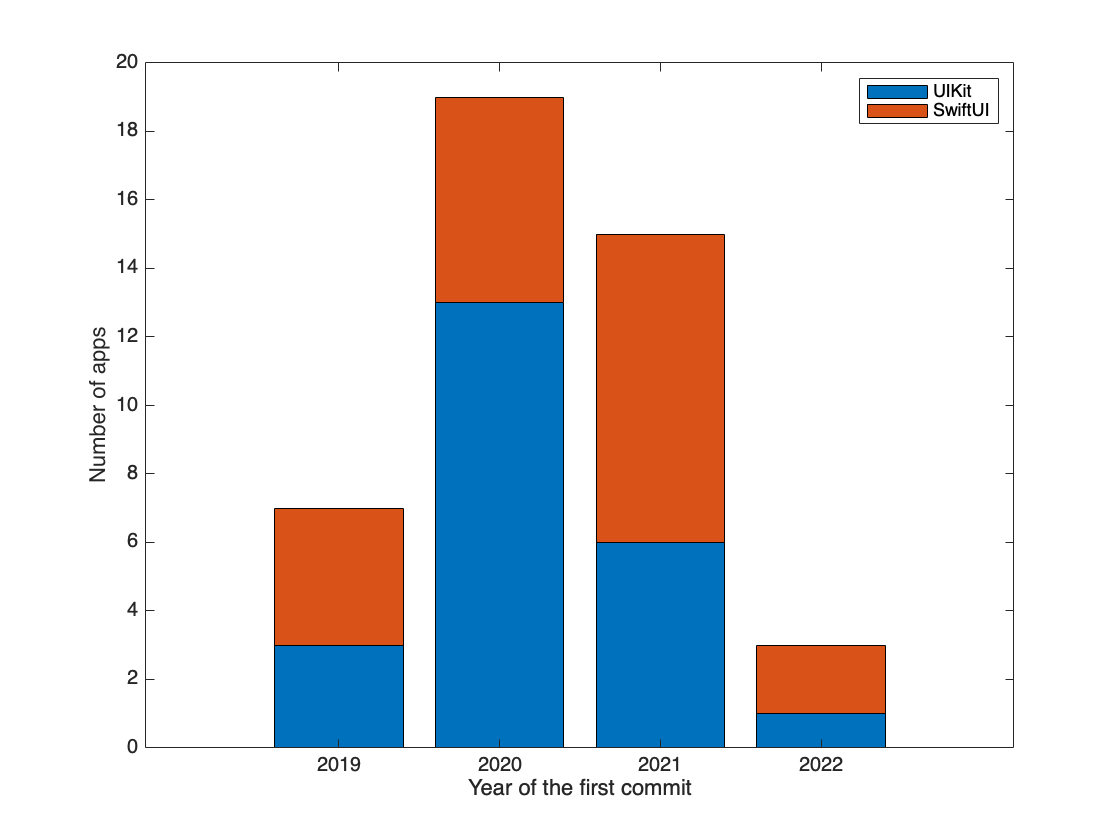


figure;
bar([2019, 2020, 2021, 2022], [UIKitCounts + bothCounts; swiftUICounts;], 'stacked');

legend("UIKit", "SwiftUI")
xlabel('Year of the first commit') 
ylabel('Number of apps')